optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

% Load data
% load pricevolumedata.mat ;
dataInput = load("pricevolumedata.mat")

dataInput = struct with fields:
    closepriceTT: [1212×665 timetable]
     highpriceTT: [1212×665 timetable]
      indexclean: [1212×6 timetable]
      lowpriceTT: [1212×665 timetable]
     openpriceTT: [1212×665 timetable]
        volumeTT: [1212×665 timetable]


% Test objective and constraints function
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [120  100 2   5   5  10   120 20  5   5   3]

paramsInput =    120   100     2     5     5    10   120    20     5     5     3


tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
[portDailyRetTT] = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = sol

paramsInput =     77   113     5     1     9     2   122    14     8     3     3


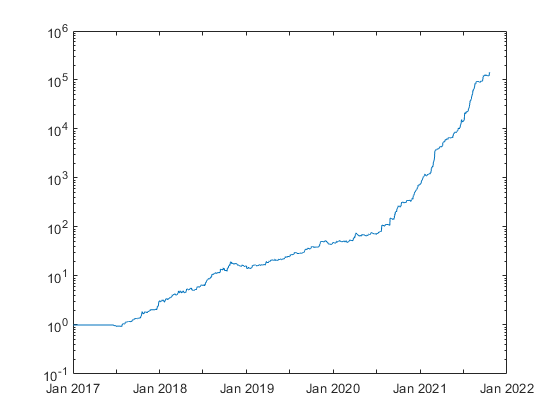

portEndValue = 1.4373e+05

portMinValue = 0.9229

portMaxValue = 1.4373e+05

MaxDD = 0.2729

MaxDDIndex =    469
   517


drawdownDate = 2×1 datetime array
   2018-10-26
   2019-01-02


sharpeRatio = 4.8898

FortValueAtOptPoint = 1.2142e+05

PortRetOptPtEnd = 0.1838

optimPointDate = datetime
   2021-10-13


nYear = 4.8027

CAGR = 10.8543

dailyRetAvg = 0.0104

dailyRetMin = -0.1161

dailyRetMax = 0.4095

CAGR = 10.8543

tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
[portDailyRetTT] = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, optimPoint)

Define upper, lower bound and constraints

% Define upper, lower and bound 
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [70   100 2   3   3   5   90  10  3   1   0] ;
ub              = [150  150 8   6   8  15   250 30  5   5   8] ;

% lb              = [60   50  2   1  2   0   60  5   3   1   0] ;
% ub              = [250  200 60  10 10  15  250 30  5   5   8] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
intcon = 1:nvars ;

% Objective & constraints function
optimPoint = 60

optimPoint = 60

dataInput = load("pricevolumedata.mat") ;

f =  @(x)objconstrFcn(x, dataInput, optimPoint);
% f =  @(x)objFcn(x, dataInput, optimPoint);

nvars = 11 ;

% Set options
maxFcnEval = 200;
opts = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-4, "UseParallel", true, "MaxFunctionEvaluations",maxFcnEval);


Call `surrogateopt` to solve the problem

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
Objective or constraint function returned NaN.


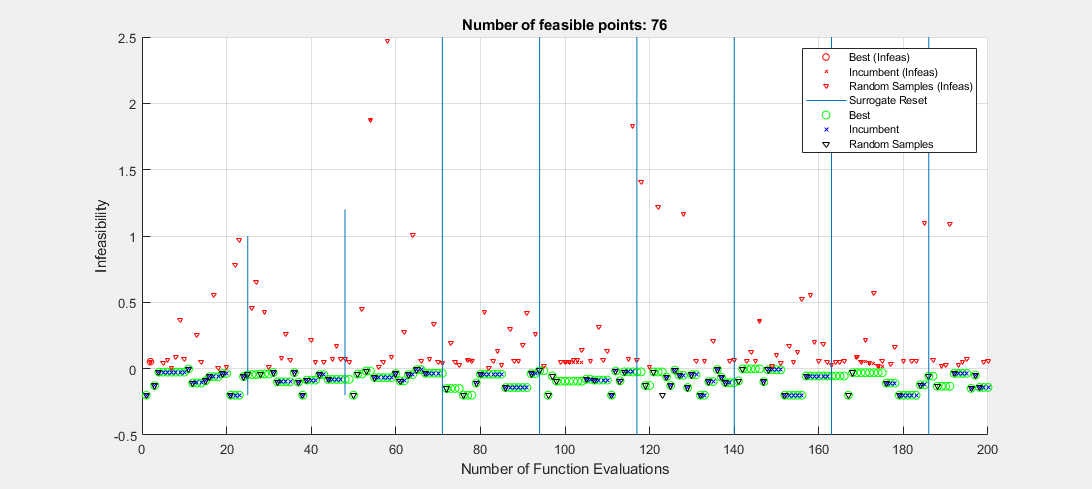

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    136   136     6     5     8     6   213    26     4     5     8



fval =

  1×0 empty double row vector



exitflag = 0

outpt = struct with fields:
        elapsedtime: 233.9315
          funccount: 200
    constrviolation: -0.1412
               ineq: [-0.1412 -0.5240]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


% Call surrogateopt to solve the problem
rng default % For reproducibility
[sol,fval,exitflag,outpt] = surrogateopt(f,lb,ub,intcon,opts)

% Examine result of optimized params
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = sol

paramsInput =     77   113     5     1     9     2   122    14     8     3     3


tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
[portDailyRetTT] = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = sol

paramsInput =     77   113     5     1     9     2   122    14     8     3     3


portEndValue = 1.4373e+05

portMinValue = 0.9229

portMaxValue = 1.4373e+05

MaxDD = 0.2729

MaxDDIndex =    469
   517


drawdownDate = 2×1 datetime array
   2018-10-26
   2019-01-02


sharpeRatio = 4.8898

FortValueAtOptPoint = 1.2142e+05

PortRetOptPtEnd = 0.1838

optimPointDate = datetime
   2021-10-13


nYear = 4.8027

CAGR = 10.8543

dailyRetAvg = 0.0104

dailyRetMin = -0.1161

dailyRetMax = 0.4095

CAGR = 10.8543

tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
[portDailyRetTT] = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, optimPoint)